clearvars;
clc;


## Set Arguments 

Download a pretrained detector to avoid having to wait for training to complete. If you want to train the detector, set the `doTraining` variable to true.

doTraining = true; % set true to train new network
visualizeAnchorBoxes = true; % set true to see plot of anchorbox # vs meanIoU
testDataset = true;  % set true to test new network on dataset


### Load in Network to begin Transfer Learning

featureExtractionNetwork = resnet101;
network_string = "resnet101_03_02"; % this is to append to table, must be str of network

Select a layer in the network that is about 16x smaller than the input size. For a 224 x 224 input image size we found that a ReLu layer of a size of 14x14x1024 works relatively well.

featureLayer = 'res4b20_relu'; % chosen googlenet layer
inputSize = [224 224 3];

## import Ground Truth

if ~exist('../video_data_03_02')
    mkdir('../video_data_03_02')
end
gTruth = load("labels_02_29.mat");

gTruth = gTruth.gTruth

gTruth =   groundTruth with properties:

          DataSource: 'D:\GP050676.MP4'
    LabelDefinitions: [4×4 table]
           LabelData: [47580×4 timetable]

Invalid DataSource. Use changeFilePaths to update DataSource.

oldpath = "D:\GP050676.MP4"; %% old data source
newpath = "..\GP050676.MP4"; %% if switching computers, this is the path where the video is
alterpaths = {[oldpath newpath]};
unresolved = changeFilePaths(gTruth,alterpaths)


unresolved = 

  0×0 empty string array



trainingDataTable = objectDetectorTrainingData(gTruth, "WriteLocation","../video_data_03_02", 'NamePrefix','facility');


Write images extracted for training to folder: 
    ../video_data_03_02

Writing 903 images extracted from GP050676.MP4...Completed.


## Split Data

rng(0);
shuffledIndices = randperm(height(trainingDataTable));
train_splitPercentage = 0.80;
train_idx = floor(train_splitPercentage * length(shuffledIndices) );
trainingDataTbl = trainingDataTable(shuffledIndices(1:train_idx),:);

val_splitPercentage = .10; % splits 
val_idx = floor(val_splitPercentage * length(shuffledIndices));
val_start_index = train_idx+1; val_stop_index = val_start_index+val_idx;
valDataTbl = trainingDataTable(shuffledIndices(val_start_index:val_stop_index),:);

testDataTbl = trainingDataTable(shuffledIndices(val_stop_index+1:end),:);


## Augment Training Data

rng(0);
rand_images = randi([1 height(trainingDataTbl)], 25, 1); % create 25 x 1 array to get 25 random images
dir_str = '../video_data_03_02/'

dir_str = '../video_data_03_02/'

for i = 1:length(rand_images)
    for j = 1:15
        img_tbl = trainingDataTbl(rand_images(i),:); %read row
        img = table2cell(img_tbl);
        save_image = pre_aug_Image(img, inputSize);
        save_image_str = strcat('facility_aug_', int2str(i*j),'.png');
        img_path = strcat(dir_str,save_image_str);
        imwrite(save_image, img_path, 'png')
        % append to the table
        img{1} = img_path;
        img = cell2table(img, 'VariableNames',img_tbl.Properties.VariableNames);
        trainingDataTbl = [trainingDataTbl;img];
    end
end


## Create Datastores for Data sets

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:5));

imdsVal = imageDatastore(valDataTbl{:,'imageFilename'});
bldsVal = boxLabelDatastore(valDataTbl(:,2:5)); 

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});  
bldsTest = boxLabelDatastore(testDataTbl(:,2:5));

trainingData = combine(imdsTrain,bldsTrain);
valData = combine(imdsVal, bldsVal);
testData = combine(imdsTest,bldsTest);

## Preprocess and Augment Images

inputSize = [224 224 3];

trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));

### Repeat Preprocessing for ValData and TestData

preprocessedValData = transform(valData,@(data)preprocessData(data,inputSize));

preprocessedTestData = transform(testData,@(data)preprocessData(data,inputSize));


## **Determine Best Number of Anchors**

Sweep over all possible anchors to determine best fit uncomment to see the graph of performance

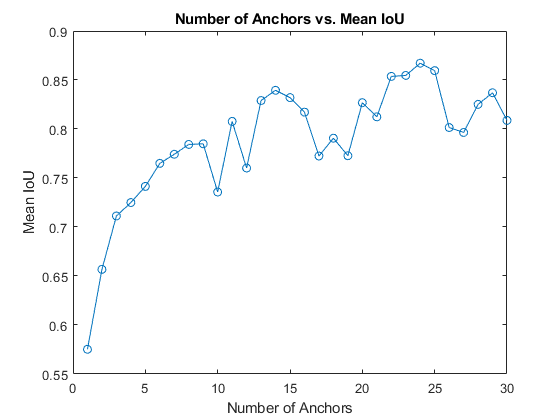

    if visualizeAnchorBoxes
    maxNumAnchors = 30;
    meanIoU = zeros([maxNumAnchors,1]);
    anchorBoxes = cell(maxNumAnchors, 1);
    for k = 1:maxNumAnchors
        % Estimate anchors and mean IoU.
        [anchorBoxes{k},meanIoU(k)] = estimateAnchorBoxes(trainingDataForEstimation,k);    
    end
    
    figure
    plot(1:maxNumAnchors,meanIoU,'-o')
    ylabel("Mean IoU")
    xlabel("Number of Anchors")
    title("Number of Anchors vs. Mean IoU")
end

## Create a YOLO v2 Object Detection Network

A YOLO v2 object detection network is composed of two subnetworks. A feature extraction network followed by a detection network. The feature extraction network is typically a pretrained CNN (for detials, see [Pretrained Deep Neural Networks](docid:nnet_ug#bvf9ych-1)). This example uses ResNet-50 for feature extraction. You can also use other pretrained networks such as MobileNet v2 or ResNet-18 can also be used depending on application requirements. The detection sub-network is a small CNN compared to the feature extraction network and is composed of a few convolutional layers and layers specific for YOLO v2.

Use the [`yolov2Layers`](docid:vision_ref#mw_b1e7b78e-2ce3-4d2f-ad8d-f5acd725f170) function to create a YOLO v2 object detection network automatically given a pretrained ResNet-50 feature extraction network. `yolov2Layers` requires you to specify several inputs that parameterize a YOLO v2 network:

- Network input size

- Anchor boxes

- Feature extraction network 

Define the number of object classes to detect.

numClasses = width(trainingDataTable)-1;

## Visually Inspect, Determine A Good NumAnchors

numAnchors = 11;

**Changed from trainingData in the example to trainingDataForEstimation to put it in the correct format.**

[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation, numAnchors)

anchorBoxes =      8    20
    29    16
    80    26
    36    33
    16    19
    56    32
    24    32
    31    23
    48    22
    70    43


meanIoU = 0.7889

For more information on choosing anchor boxes, see [Estimate Anchor Boxes from Training Data](docid:vision_ug#mw_671cb7a6-5a7a-4147-acf3-3e1fd7d3dfd7) (Computer Vision Toolbox™) and [Anchor Box Basics](docid:vision_ug#mw_f9f22f48-0ad0-4f37-8bc1-22a2046637f2).

### Create the YOLO v2 object detection network. 

lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

You can visualize the network using `analyzeNetwork` or Deep Network Designer from Deep Learning Toolbox™.

If more control is required over the YOLO v2 network architecture, use Deep Network Designer to design the YOLO v2 detection network manually. For more information, see [Design a YOLO v2 Object Detection Network](docid:vision_ug#mw_bcbd5375-ed75-4616-b57b-469e29139033).

## Train YOLO v2 Object Detector

Use `trainingOptions` to specify network training options. Set `'CheckpointPath'` to a temporary location. This enables the saving of partially trained detectors during the training process. If training is interrupted, such as by a power outage or system failure, you can resume training from the saved checkpoint.

learningRate = 1e-3;
epochSize = 100;
solverMethod = 'sgdm';
featureLayerString = string(featureLayer);
miniBatchsize = 16;
period = 10;
drop_factor = .95;
momentum = 0.975;
options = trainingOptions(solverMethod, ...
        'MiniBatchSize', miniBatchsize, ....
        'InitialLearnRate',learningRate, ...
        'MaxEpochs',epochSize,...
        'CheckpointPath', tempdir, ...
        'LearnRateSchedule', 'piecewise', ...
        'LearnRateDropPeriod', period, ...
        "LearnRateDropFactor", drop_factor, ...
        'Momentum', momentum, ...
        'Shuffle','never');

Use [`trainYOLOv2ObjectDetector`](docid:vision_ref#mw_0ff9d26a-9a79-4333-a1b1-ba03c8539ee3) function to train YOLO v2 object detector if `doTraining` is true. Otherwise, load the pretrained network.

   if doTraining       
    % Train the YOLO v2 detector.
    [detector,info] = trainYOLOv2ObjectDetector(trainingDataForEstimation,lgraph,options);
else
    % Load another object detector and evaluate that performance
    ObjectDetector = load('YOLOv2_MBSize_10_MaxEpoch_20_InitLearnRate_1e-3_NumAnchors_15_Acc_11.mat');
    detector = ObjectDetector.detector;
end

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* can
* glass
* other
* plastic

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |         9.96 |         99.3 |          0.0010 |
|       1 |          50 |       00:01:37 |         2.66 |          7.1 |          0.0010 |
|       2 |         100 |       00:03:18 |         2.16 |          4.7 |          0.0010 |
|       3 |         150 |       00:04:57 |         2.36 |          5.6 |          0.0010 |
|       3 |         200 |       

This example was verified on an NVIDA™ Titan X GPU with 12 GB of memory. If your GPU has less memory, you may run out of memory. If this happens, lower the `'MiniBatchSize'` using the `trainingOptions` function. Training this network took approximately 7 minutes using this setup. Training time varies depending on the hardware you use.

As a quick test, run the detector on one test image. Make sure you resize the image to the same size as the training images.

**TEST DETECTOR **

Tests the detector on an image from the test dataset reserved earlier

if testDataset
    % test detector on    all the testing data to see if there is any detection
    detectedImages = 0;
    missedImages = 0;
    imageIndices = 1;
    for i = 1:length(valDataTbl.imageFilename) 
        I = imread(valDataTbl.imageFilename{i});
        I = imresize(I,inputSize(1:2));
        [bboxes,scores] = detect(detector,I);
        
        if(~isempty(bboxes))
            I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
          
            detectedImagesIndexArray(imageIndices) = i;
            imageIndices = imageIndices + 1;
            
            detectedImages =  detectedImages + 1;
        else
            missedImages = missedImages + 1;
        end
    end
    detector_accuracy = detectedImages/height(valDataTbl) * 100;
    fprintf('total images: %d\n',length(valDataTbl.imageFilename));
    fprintf('detected images: %d\n',detectedImages);
    fprintf('missed images: %d\n',missedImages);
    fprintf('Accuracy Percentage, detected/missed: %f\n',detectedImages/length(valDataTbl.imageFilename) * 100);
end

total images: 91


detected images: 50


missed images: 41


Accuracy Percentage, detected/missed: 54.945055


## Display A Detected Image From The Detected Images Set

Usage: replace* detectedImagesIndexArray(3) *with *detectedImagesIndexArray( your desired number in the range of detectedImagesIndex range ) *

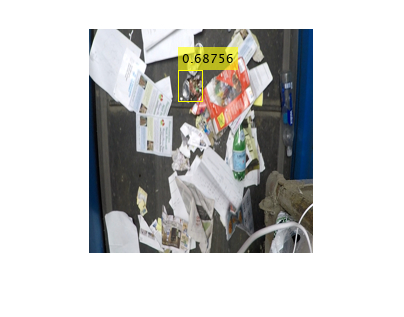

    if detectedImages > 0 
        figure
        img = imread(valDataTbl.imageFilename{detectedImagesIndexArray(2)});
        img = imresize(img,inputSize(1:2));
        [bboxes,scores] = detect(detector,img);
        if(~isempty(bboxes))
            img = insertObjectAnnotation(img,'rectangle',bboxes,scores); 
        end
        imshow(img)
    end

## Evaluate Detector Using Test Set

Evaluate the trained object detector on a large set of images to measure the performance. Computer Vision Toolbox™ provides object detector evaluation functions to measure common metrics such as average precision (`evaluateDetectionPrecision`) and log-average miss rates (`evaluateDetectionMissRate`). For this example, use the average precision metric to evaluate performance. The average precision provides a single number that incorporates the ability of the detector to make correct classifications (precision) and the ability of the detector to find all relevant objects (recall).

Run the detector on all the test images.

detectionResults = detect(detector, preprocessedValData);

Evaluate the object detector using average precision metric.

[ap,recall,precision] = evaluateDetectionPrecision(detectionResults, preprocessedValData);
save(network_string, 'detector', 'ap', 'recall', 'precision'); % save detector

## Supporting Functions

function B = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.
B = cell(size(A));

I = A{1};
sz = size(I);
if numel(sz)==3 && sz(3) == 3
    I = jitterColorHSV(I,...
        'Contrast',0.3,...
        'Hue',0,...
        'Saturation',0.2,...
        'Brightness',0.2);
end

% Randomly flip and scale image.
% tform = randomAffine2d('XReflection',true,'Scale',[1 1.1]);
tform = randomAffine2d('XReflection',true,'Scale',[1 1.1], "YReflection", true);
rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');
B{1} = imwarp(I,tform,'OutputView',rout);

% Apply same transform to boxes.
[B{2},indices] = bboxwarp(A{2},tform,rout,'OverlapThreshold',0.25);
B{3} = A{3}(indices);

% Return original data only when all boxes are removed by warping.
if isempty(indices)
    B = A;
end
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to the targetSize.
scale = targetSize(1:2)./size(data{1},[1 2]);
data{1} = imresize(data{1},targetSize(1:2));
data{2} = floor(data{2});
%data{2}(2) = 1;
data{2} = correctData(data{2});
data{2} = bboxresize(data{2},scale); 
end

%%
function img_to_save = pre_aug_Image(img, targetSize)
    % Resize image and bounding boxes to the targetSize.
    width = size(img);
    width = width(2);
    I = imread(img{1}); % file path
    sz = size(I);
    if numel(sz)==3 && sz(3) == 3
        I = jitterColorHSV(I,...
            'Contrast',0.3,...
            'Hue',0,...
            'Saturation',0.2,...
            'Brightness',0.2);
    end
    
    % Randomly flip and scale image
    tform = randomAffine2d('XReflection',true,'Scale',[1 1.1], "YReflection", true);
    rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');
    B = imwarp(I,tform,'OutputView',rout);
    
    % Apply same transform to boxes.
    for col = 2:width
        img{col} = floor(img{col});
        img{col} = correctData(img{col});
        img{col} = bboxwarp(img{col},tform,rout,'OverlapThreshold',0.25);
    end
    img_to_save = B;
end

%%%
function data = correctData(data)

D = size(data);
length = D(1) * D(2);
if min(data,[],'all') == 0 
   for i=1:length
       if data(i) == 0 
           data(i) = 1;
       end
   end
end

end

## References

[1] Redmon, Joseph, and Ali Farhadi. "YOLO9000: Better, Faster, Stronger." 2017 IEEE Conference on Computer Vision and Pattern Recognition (CVPR). IEEE, 2017.

*Copyright 2019 The MathWorks, Inc.*